clc;
clear all;
close all;


% Initial parameters
f1 = 50.5;
fs = 6.4*1000;
T  = 0.2;
n = fs*T

n = 1280

t = (0:n-1)/fs

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


% m = length(t);
dt = 1/((fs/f1)*f1) %1/fs;

dt = 1.5625e-04

w = 2*pi*f1;


### Real Signal

% dt = 6.2500e-04;
% load("Case 3 voltage.mat");
% x = volt_distr(:,end)';
% x = 2*((x-min(x))/(max(x)-min(x)))-1 % normalizing the data
% x = x(1:n)
% x = x + awgn(x,30)



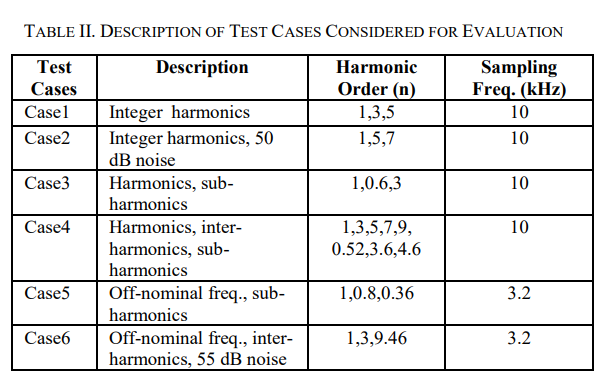

Considering this signal

x = cos(w*t) + 0.05*cos(3*w*t) + 0.02*cos(5*w*t); %% Case 1
% x = x + awgn(x,50);
tic
m = 30*2;

% x = cos(w*t) + 0.05*cos(3*w*t) + 0.02*cos(5*w*t) + 0.05*cos(6.3*w*t);
% x = awgn(x,50);


% x = cos(w*t) + 0.05*cos(3*w*t) + 0.02*cos(5*w*t) + 0.05*cos(6.3*w*t); %% Case 2
% x = x + awgn(x,50);


% x = cos(w*t) + 0.5*cos(3*w*t) + 0.2*cos(5*w*t) + 0.1*cos(7*w*t) + 0.05*cos(0.52*w*t) + 0.02*cos(3.6*w*t) + 0.001*cos(4.6*w*t); %% Case 4
% x = x + awgn(x,50);

### Henkel Matrix

Original Case of Hankel Matrix (this needs to be uncommented to run the original case)

% for k = 1:m
%     X(k,:) = x(k:(end-m+k));
% end
% X

### Toeplitz matrix

X = toeplitz(x,x)

X =     1.0700    1.0676    1.0605    1.0488    1.0328    1.0127    0.9891    0.9624    0.9329    0.9013    0.8680    0.8334    0.7978    0.7617    0.7252    0.6886    0.6518    0.6149    0.5779    0.5406    0.5029    0.4647    0.4258    0.3860    0.3452    0.3033    0.2604    0.2164    0.1714    0.1255    0.0791    0.0322   -0.0149   -0.0619   -0.1086   -0.1547   -0.2000   -0.2444   -0.2877   -0.3300   -0.3711   -0.4113   -0.4505   -0.4890   -0.5269   -0.5643   -0.6014   -0.6383   -0.6751   -0.7118
    1.0676    1.0700    1.0676    1.0605    1.0488    1.0328    1.0127    0.9891    0.9624    0.9329    0.9013    0.8680    0.8334    0.7978    0.7617    0.7252    0.6886    0.6518    0.6149    0.5779    0.5406    0.5029    0.4647    0.4258    0.3860    0.3452    0.3033    0.2604    0.2164    0.1714    0.1255    0.0791    0.0322   -0.0149   -0.0619   -0.1086   -0.1547   -0.2000   -0.2444   -0.2877   -0.3300   -0.3711   -0.4113   -0.4505   -0.4890   -0.5269   -0.5643   -0.6014   -0.6383   -0

X = X(1:m,1:end-m+1)

X =     1.0700    1.0676    1.0605    1.0488    1.0328    1.0127    0.9891    0.9624    0.9329    0.9013    0.8680    0.8334    0.7978    0.7617    0.7252    0.6886    0.6518    0.6149    0.5779    0.5406    0.5029    0.4647    0.4258    0.3860    0.3452    0.3033    0.2604    0.2164    0.1714    0.1255    0.0791    0.0322   -0.0149   -0.0619   -0.1086   -0.1547   -0.2000   -0.2444   -0.2877   -0.3300   -0.3711   -0.4113   -0.4505   -0.4890   -0.5269   -0.5643   -0.6014   -0.6383   -0.6751   -0.7118
    1.0676    1.0700    1.0676    1.0605    1.0488    1.0328    1.0127    0.9891    0.9624    0.9329    0.9013    0.8680    0.8334    0.7978    0.7617    0.7252    0.6886    0.6518    0.6149    0.5779    0.5406    0.5029    0.4647    0.4258    0.3860    0.3452    0.3033    0.2604    0.2164    0.1714    0.1255    0.0791    0.0322   -0.0149   -0.0619   -0.1086   -0.1547   -0.2000   -0.2444   -0.2877   -0.3300   -0.3711   -0.4113   -0.4505   -0.4890   -0.5269   -0.5643   -0.6014   -0.6383   -0

### Circulant Matrix

% X = toeplitz([x(1) fliplr(x(2:end))], x);
% X = X(1:m,1:end-m+1)


### Circulant + Toeplitz

% X = circ_toepl(x)
% X = X(1:m,1:end-m+1)

### Time Shift

#### Column wise (Original)

Xaug = X(:,1:end-1); Xaug2 = X(:,2:end);

No changes in the code from here

r = m; % number of modes

[U,S,V] = svd(Xaug,'econ');
Xaug1 = Xaug';
beta = size(Xaug1,2)/size(Xaug1,1)  % aspect ratio of matrix

beta = 0.0492

sigma = diag(S);             % extract singular values
% optimal threshold tau
tau = optimal_SVHT_coef(beta,0)*median(sigma);  

rank_S = rank(S);
% figure
% semilogy(sigma,'k-o','LineWidth',1.2)
% hold on
% semilogy(sigma(sigma>tau),'ro','LineWidth',1.2)
% grid on


SD = sigma(sigma>tau);
r = size(SD,1);


U_r = U(:, 1:r);
S_r = S(1:r, 1:r);
V_r = V(:, 1:r);


%%% Changed inv to pinv
Atilde = U_r'*Xaug2*V_r*pinv(S_r);
[W,lambda] = eig(Atilde);
Omega = diag(log(diag(lambda)))/dt;
phi = Xaug2*V_r*pinv(S_r)*W;


b = phi\Xaug(:,1); % mode amplitude

% for k = 1:length(t)
%     xaugdmd(:,k) = phi*exp(Omega*t(k))*b;
% end

% % % % figure;plot(t,real(xaugdmd(1,:)),'linewidth',1.5);axis tight;grid on; hold on
% % % % plot(t,x1); 

Ext_fer = imag(diag(Omega./(2*pi)));
DMDfreqs = ((log(diag((lambda))))/(2*pi*dt));


DMDpower  = abs(b)*2/sqrt(m)

DMDpower =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


max(DMDpower)

ans = 1.0000

fest = abs(imag(DMDfreqs))

fest =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


toc

Elapsed time is 0.414969 seconds.


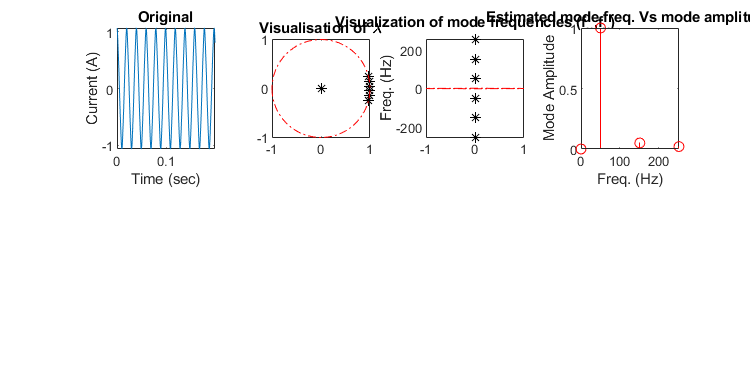


LW = 'LineWidth';

%% eigenvalue
figure('Position', [100 100 600 300]);
subplot(2,4,2);plot(lambda, 'k*');rectangle('Position', [-1 -1 2 2], 'Curvature', 1, ...
    'EdgeColor', 'r', 'LineStyle', '-.');axis(1.2*[-1 1 -1 1]);axis square;axis tight;title('Visualisation of \lambda')
subplot(2,4,3);plot(DMDfreqs, 'k*');rectangle('Position', [-1 -1 2 2], 'Curvature', 1, ...
    'EdgeColor', 'r', 'LineStyle', '-.');axis(200*[-1 1 -1 1]);axis square;ylabel('Freq. (Hz)');axis tight;title('Visualization of mode frequencies (f_u,f_v)')
subplot(2,4,4);
stem(fest,DMDpower,'r');xlabel('Freq. (Hz)');ylabel('Mode Amplitude');axis tight;title('Estimated mode freq. Vs mode amplitude')
% figure;stem(fest,DMDpower,'r');xlabel('Freq. (Hz)');ylabel('Mode Amplitude');axis tight;title('Estimated mode freq Vs amplitude')
            subplot(2,4,1);plot(t,x);axis tight;xlabel('Time (sec)');ylabel('Current (A)');axis tight;title('Original')

phase_ang = [];

function final = circ_toepl(x)

X = toeplitz([x(1) fliplr(x(2:end))], x);
X = toeplitz(X(:,1),X(:,1))
final = X;

end


